# **Noise **

% Noise Parameters
noise_power = 100e-6; % 100 uW
bandwidth = 1e6; % 1 MHz
fs = 2 * bandwidth; % Nyquist
duration = 0.1; % Signal duration
j = sqrt(-1); % im unit

% PSD
noise_density = noise_power / bandwidth; % Watt/Hz

% Generate complex AWGN
num_samples = fs * duration;
noise_signal = sqrt(noise_density) * (randn(num_samples, 1) + j * randn(num_samples, 1));

% Compute autocorrelation
autocorr_noise = xcorr(noise_signal, 'biased');

% Apply FFT to the autocorrelation to get the PSD
psd_noise = fftshift(fft(autocorr_noise));

% Frequency axis
f_noise = linspace(-bandwidth/2, bandwidth/2, length(psd_noise));

% Convert PSD to dBm/Hz
psd_noise_dBm_Hz = 10 * log10(abs(psd_noise)) + 30;

# **Signal**

% Signal Parameters
signal_power_dBm = 0; % dBm
signal_power = 10^((signal_power_dBm - 30) / 10); % Watt
signal_freq = 200e3; % 200 kHz

% Generate sinusoidal signal
t = (-num_samples/2:num_samples/2 - 1)' / bandwidth; % Time vector
amplitude = sqrt(signal_power); % Convert power to amplitude
sin_signal = amplitude * cos(2 * pi * signal_freq * t); % Real Signal
complex_signal = amplitude * exp(j * 2 * pi * signal_freq * t); % Complex Signal

% Compute autocorrelation
autocorr_sin = xcorr(sin_signal, 'biased');
autocorr_complex = xcorr(complex_signal, 'biased');

% Apply FFT to the autocorrelation to get the PSD
psd_sin = fftshift(fft(autocorr_sin));
psd_complex = fftshift(fft(autocorr_complex));

% Frequency axis
f_sig = linspace(-bandwidth/2, bandwidth/2, length(psd_sin));

% Convert PSD to dBm/Hz
psd_sin_dBm_Hz = 10 * log10(abs(psd_sin)) + 30;
psd_complex_dBm_Hz = 10 * log10(abs(psd_complex)) + 30;

# **Plot, SNR & Noise Floor**

% Display the noise floor
disp(['Noise floor: ', num2str(mean(psd_noise_dBm_Hz)), ' dBm/Hz']);

Noise floor: -69.5027 dBm/Hz


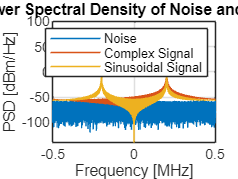


% Plot the PSDs
figure;
plot(f_noise/1e6, psd_noise_dBm_Hz);
hold on;
plot(f_sig/1e6, psd_complex_dBm_Hz);
plot(f_sig/1e6, psd_sin_dBm_Hz);
title('Power Spectral Density of Noise and Signal');
xlabel('Frequency [MHz]');
ylabel('PSD [dBm/Hz]');
grid on;
legend('Noise', 'Complex Signal', 'Sinusoidal Signal');